# 02686 - Scientific Computing for Differential Equations - Exam 

## 7 - ESDIRK23

## ESDIRK23

x0 = [1.0;1.0];
N = 10000;
t0 = 0; tf = 50;
h0 = (tf-t0)/N;

abstol = 1e-6;
reltol = 1e-6;

## For mu = 3

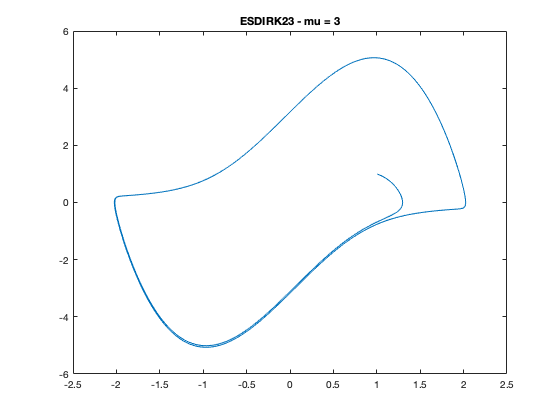

mu = 3;
[T,X,G,info,stats] = ESDIRK23(@VanderPolFun,@VanderPolJac,t0,tf,x0,h0,abstol,reltol,mu);

plot(X(:,1),X(:,2));
title('ESDIRK23 - mu = 3')


options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);

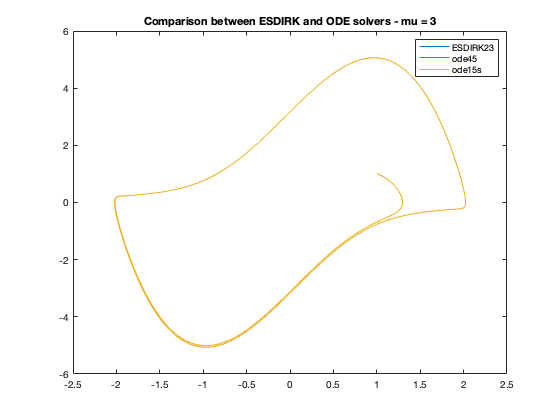

plot(X(:,1),X(:,2));
hold on 
plot(X2(:,1),X2(:,2));
hold on 
plot(X3(:,1),X3(:,2));
hold off
legend('ESDIRK23','ode45','ode15s')
title('Comparison between ESDIRK and ODE solvers - mu = 3')

## For mu = 20

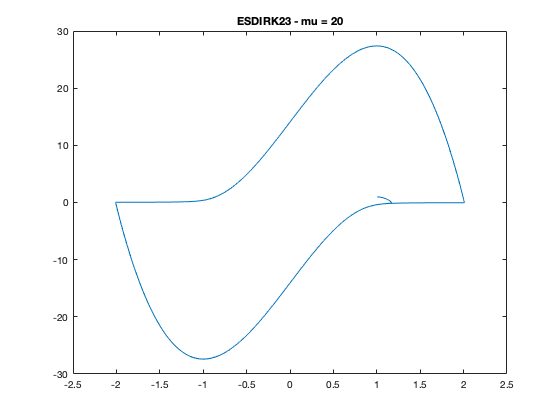

mu = 20;
[T,X,G,info,stats] = ESDIRK23(@VanderPolFun,@VanderPolJac,t0,tf,x0,h0,abstol,reltol,mu);
plot(X(:,1),X(:,2));
title('ESDIRK23 - mu = 20')


options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);

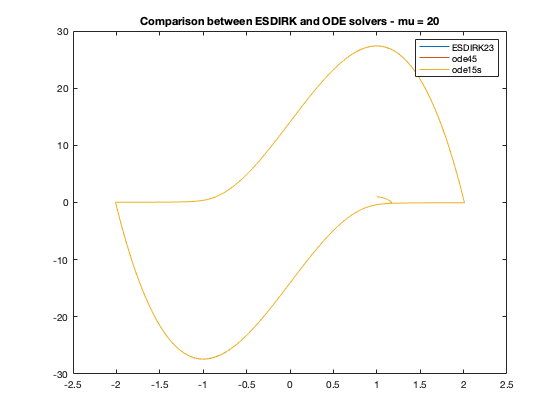

plot(X(:,1),X(:,2));
hold on 
plot(X2(:,1),X2(:,2));
hold on 
plot(X3(:,1),X3(:,2));
hold off
legend('ESDIRK23','ode45','ode15s')
title('Comparison between ESDIRK and ODE solvers - mu = 20')

## Stability Plot

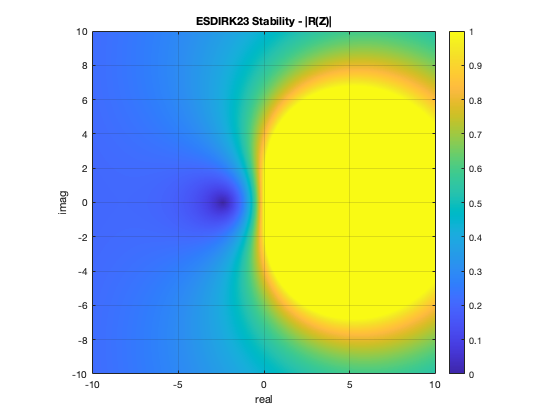

% Stability plot

alpha = -10:0.01:10;
beta = -10:0.01:10;

nreal = length(alpha);
nimag = length(beta);

absR = zeros(nreal,nimag);

% For ESDIRK23 :
gamma = 1-1/sqrt(2);
a31 = (1-gamma)/2;
AT = [0 gamma a31;0 gamma a31;0 0 gamma];
b  = AT(:,3);
A = AT';
I = eye(size(A));
e = ones(size(A,1),1);

for kreal = 1:nreal 
    for kimag = 1:nimag 
        z = alpha(kreal)+i*beta(kimag);
        tmp = (I-z*A)\e;
        R = 1 + z*b'*tmp;
        absR(kimag,kreal) = abs(R);
    end
end

imagesc(alpha,beta,absR,[0,1]);
colorbar
grid on
axis image
axis xy
xlabel('real');
ylabel('imag');
title('ESDIRK23 Stability - |R(Z)|');